LQR (Observador)

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

Espaço de estados

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];


B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];


C = [1,0,0];


D = zeros(1,3);


E = [1/m_u; 1/m_v; 0]; %entrada de disturbio

B_novo = [B E];



D_novo = [D zeros(size(C,1), size(E,2))];



t_ = 0:0.01:30;
dim= size(t_);
dimT = dim(2);

Para o Sistema

Q = diag([50000,45000,40000]);

R_ = diag([0.002,0.0004,0.005]);

K = lqr(A, B, Q, R_);
F = (A-B*K);

Para o Observador

Q_obs = diag([50, 45, 40]);

R_obs = diag([2]);

[K_obs ,S ,R_obs] = lqr(A.', C.', Q_obs, R_obs);
F_obs = (A-K_obs'*C);


Descretização e condições iniciais e entradas

x0 = [0;0;0];

u1_ = zeros(size(t_));


u2_ = 0*ones(size(t_));


w = 0*sin(2*pi()*0.1*t_);


u3_ = zeros(size(t_));

u_ = [u1_;u2_;u3_;w];

u_2 = [u1_;u2_;u3_];


Sistema com x e x^


Gamma = [A-B*K, B*K;
         zeros(3,3), A-K_obs'*C];

Bsis = [eye(6,3)];

Csis = [eye(6)];

Dsis = [eye(6,3)];

Bsis = [B_novo; B_novo];

Bsis_novo = [B_novo;B_novo];

Csis = [eye(6)];

Dsis = [zeros(6,3)];
Dsis_novo = [zeros(6,4)];


x_obs = zeros(3, 1);
xch_obs = 0.5*ones(3, 1);
cond_inicial = [x_obs; xch_obs];


sys1 = ss(F,B_novo,C,D_novo);
sys2 = ss(Gamma, Bsis_novo, Csis, Dsis_novo);


U1 = ones(1, dimT);
U0 = zeros (1, dimT);
U_ = [U0; U1; U1];


y1 = lsim(sys1, u_, t_, x_obs); % controlador
y2 = lsim(sys2, u_, t_, cond_inicial); %observador


Plots

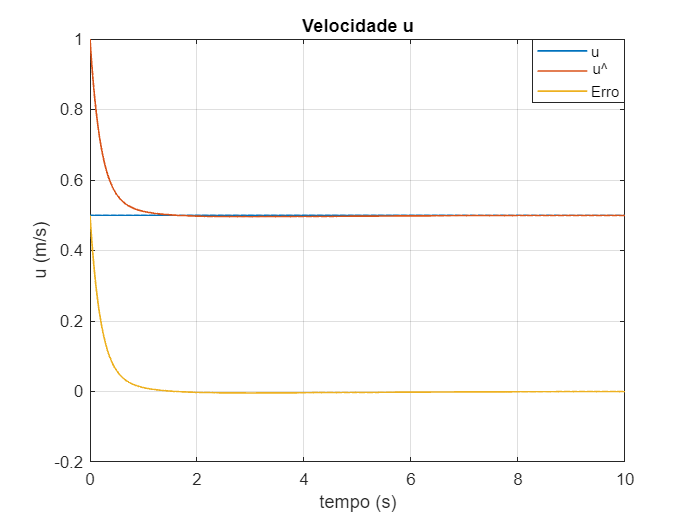

u1 = U + y1(:,1);
% v1 = V + y1(:,2);
% r1 = R + y1(:,3);
u2 = U + y2(:,4);
v2 = V + y2(:, 5);
r2 = R + y2(:, 6);

e_u = -(u1-u2);
% e_v = -(v1-v2);
% e_r = -(r1-r2);

figure(1) 
plot(t_, u1, 'LineWidth', 1) 
hold on
grid on
plot(t_, u2, 'LineWidth', 1)
plot(t_,e_u, 'LineWidth', 1)
title('Velocidade u') 
xlabel('tempo (s)') 
ylabel('u (m/s)')
legend('u', 'u\^', 'Erro') 
xlim ([0 10])
hold off 

legend("Position", [0.77013,0.80139,0.13386,0.12283])

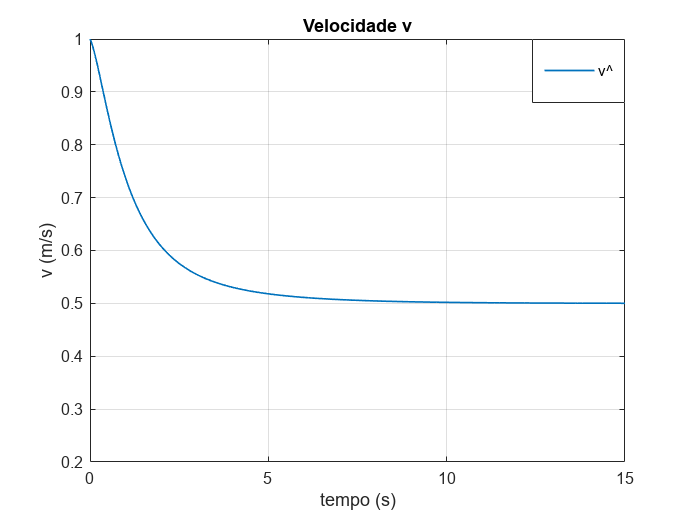



figure(2) 
plot(t_, v2, 'LineWidth', 1) 
grid on
title('Velocidade v') 
xlabel('tempo (s)')
ylabel('v (m/s)') 
legend('v\^') 
xlim ([0 15])
ylim([0.2 1])
hold off 

legend("Position", [0.77013,0.80139,0.13386,0.12283])

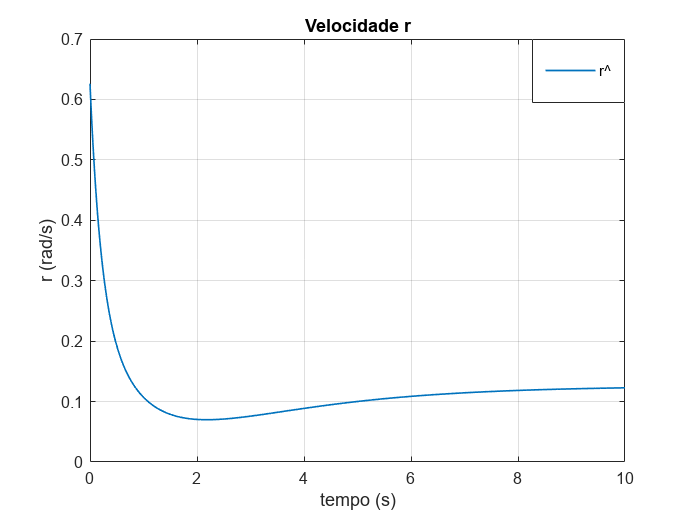



figure(3) 
plot(t_, r2, 'LineWidth', 1)
grid on
title('Velocidade r') 
xlabel('tempo (s)')
ylabel('r (rad/s)') 
legend('r\^')
xlim ([0 10])
hold off 
legend("Position", [0.77013,0.80139,0.13386,0.12283])